## Feladat 1

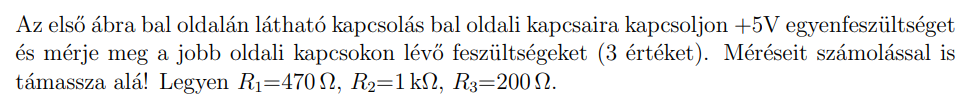

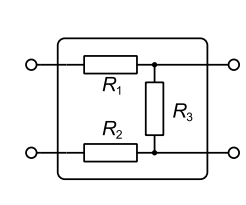

### Adatok

R_1 = 470;
R_2 = 1000;
R_3 = 200;
U_g = 5;

### Képletek


$$I=\frac{U}{R}$$


$R_e =R_1 +R_2 +\ldotp \ldotp +R_n$ Soros kapcsolásnál

### Számolás

Számojluk ki az eredető ellenállást és az áramkörben haladó áram erősségét.

R_e = R_1 + R_2 + R_3;
I = U_g / R_e;

Majd utána az egyes ellenállások értékét számoljuk ki az Ohm törvényével.

U_r1 = I * R_1

U_r1 = 1.4072

U_r2 = I * R_2

U_r2 = 2.9940

U_r3 = I * R_3

U_r3 = 0.5988

### Ellenőrzés

[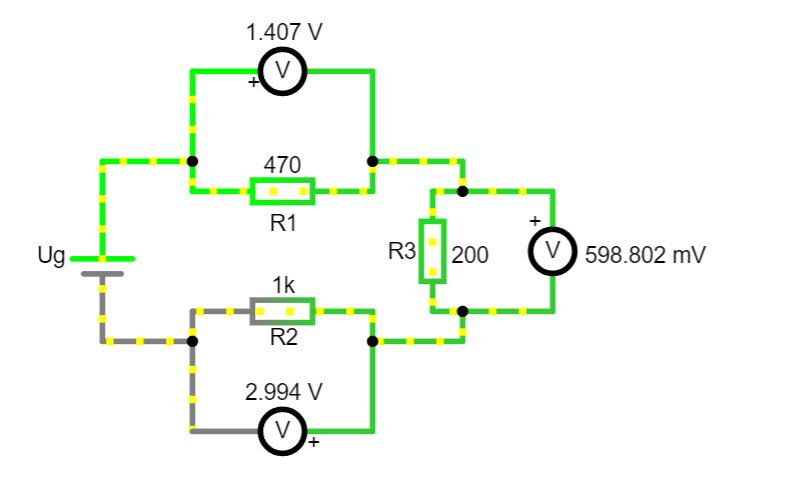](https://www.falstad.com/circuit/circuitjs.html?ctz=CQAgjCAMB0l3BWcMBMcUHYMGZIA4UA2ATmIxAUgpABZsKBTAWjDACgA3cQkFGqsD0FURtKklEwEbAE4hCNbgMLLRNDJFlLefeYpS6B8NgHdu2weBqLNZy2Gt6rN00+FvHtiyoufX7h0V3Yh4vBWcnEKh-Hj4qcLjoswT+JwMXZP1UhLw8JO10gtSvd0TS3PzS1LQ8xJKfQN58CK8aiLb3VubEtsLNOTBiFAshnRsmrtrdQeG+-1HS5s7XDp8UBCEfSbHeDZ3NAAcCipy8+hE2I-XNqmud8+ij8KjgngfNAA9kJDA8CDA0OA8IogsMAErsL6CPKDIR4eiDYi0cDg7BsKGQJB8YYA240JCgkBglDokAsJGDPJMfSQCCEgCqAHM2EA)

## Feladat 2

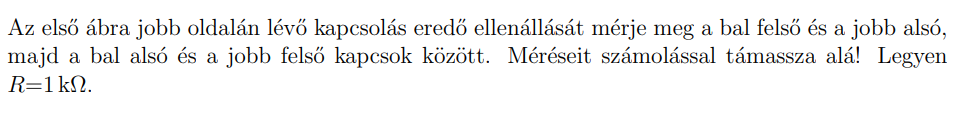

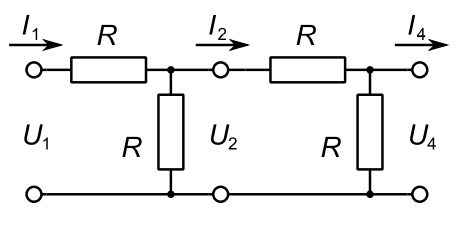

### Adatok

### Képletek


$$I=\frac{U}{R}$$


$R_e =R_1 +R_2 +\ldotp \ldotp +R_n$ Soros kapcsolásnál

$R_e =\frac{1}{\frac{1}{R_1 }+\frac{1}{R_2 }+\ldotp \ldotp +\frac{1}{R_n }}$ Párhuzamos kapcsolásnál

### Számolás

#### Jobb felsőtől bal alsóba

[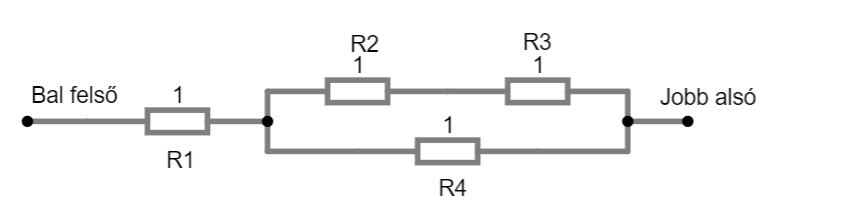](https://www.falstad.com/circuit/circuitjs.html?ctz=CQAgjCAMB0l3BWcMBMcUHYMGZIA4UA2ATmIxAUgpABZsKBTAWjDACgB3cQ8DHmvLx6Q2AJ1qCwfcDRpCo4TjLlSeYWeGIooS9Sul7uVEeLBbN2lHknmq7UxrCEqKGnecL7IV+6rZsah52uo7mZtrhOlxWNtr+arZK8RYgyapRqQFGmWrSIlxp0gGSeWwAHuCShDyEKiS04NoAQgCGADYAOgDOAGYMbV2AioDlqQj0TuRu+lQq2gBSAPYARkvd7V0AzyPELpAQYJBIaHKzIABK7BVg1uDYxN6Q4zTap2coI1Z22IIoxEjqEFe2A+2COTm8lG8ZgaYG0ZxobCAA)

Először a párhuzamos részzben lévő $R_{\textrm{ps}} =R+R$ értéket kell kiszámolni, utána a párhuhuzamos $R_{\textrm{ep}} =\frac{1}{\frac{1}{R}+\frac{1}{R_{\textrm{ps}} }}$ értéket kell kiszámolni és végül a párhuzamos eredő és az első ellenállás értékét kell kiszámolni: $R_e =R+R_{\mathrm{ep}}$

R_1 = 1;
R_2 = 1;
R_3 = 1;
R_4 = 1;
R_ps = R_2 + R_3;
R_ep = 1 / ((1 / R_4) + (1 / R_ps));
R_e = R_1 + R_ep

R_e = 1.6667

#### Ellenőrzés

[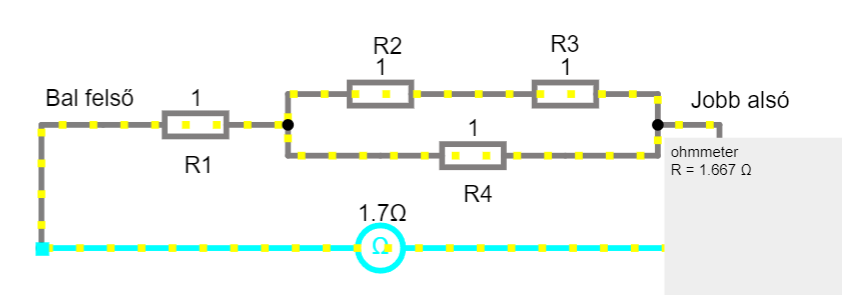](https://www.falstad.com/circuit/circuitjs.html?ctz=CQAgjCAMB0l3BWcMBMcUHYMGZIA4UA2ATmIxAUgpABZsKBTAWjDACgB3cQ8DHmvLx6Q2AJ1qCwfcDRpCo4TjLlSeYWeGIooS9Sul7uVEeLBbN2lHknmq7UxrCEqKGnecL7IV+6rZsah52uo7mZtrhOlxWNtr+arZK8RYgyapRqQFGmWrSIlxp0gGSeWwAHuCShDyEKiS04NoAQgCGADYAOgDOAGYMbV2AioDlqQj0TuRu+lQq2gBSAPYARkvd7V0AzyPELpAQYJBIaHKzIABK7BVg1uDYxN6Q4zTap2coI1Z22IIoxEjqEFe2A+2COTm8lG8ZgaYG0ZxoulygW8bgyxXk6J8OhQ4MxqPBWOMsD2bCAA)

### Bal alsótól jobb felsőbe

[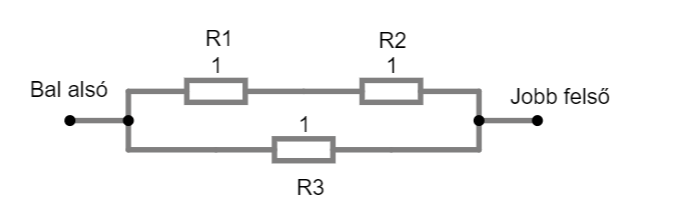](https://www.falstad.com/circuit/circuitjs.html?ctz=CQAgjCAMB0l3BWcMBMcUHYMGZIA4UA2ATmIxAUgpABZsKBTAWjDACgB3cMFcDQ8DRp8BkToOFh+E8MV5iuYISJlhCVMQCdZvMHJAo8eHVHBttSyeoM0qajWe0pb4a9mwD7p9ouV7d+v5Q4obGQe6e+gogESaxUqLi8W4eKtHx0h5h0mIAHiDEdoT0YNi6hAKSvABCAIYANgA6AM4NzQDPbPnYCCWE5LbkUlRVIABSAPYARlMtAGYM9c2AioBd4HiS2JKk4NgD4LwASuz5hhClAijEntjEtAcghyhrKKkoUgYIECho9zyP2DYQA)

Először a párhuzamos szakaszokból a felsőben kell $R_{\mathrm{pe}} =R+R$ ellenállást számolni, aztán a párhuzamos $R_e =\frac{1}{\frac{1}{R_{\mathrm{pe}} }+\frac{1}{R}}$ -vel megkapjuk a megoldást.

R_1 = 1;
R_2 = 1;
R_3 = 1;
R_pe = R_1 + R_2;
R_e = 1 / ( (1 / R_pe) + (1 / R_3))

R_e = 0.6667

#### Ellenőrzés

[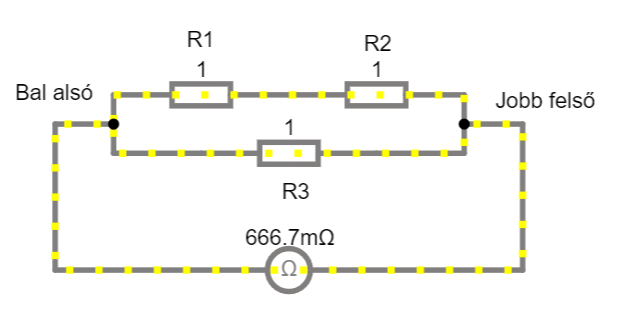](https://www.falstad.com/circuit/circuitjs.html?ctz=CQAgjCAMB0l3BWcMBMcUHYMGZIA4UA2ATmIxAUgpABZsKBTAWjDACgB3cMFcDQ8DRp8BkToOFh+E8MV5iuYISJlhCVMQCdZvMHJAo8eHVHBttSyeoM0qajWe0pb4a9mwD7p9ouV7d+v5Q4obGQe6e+gogESaxUqLi8W4eKtHx0h5h0mIAHiDEdoT0YNi6hAKSvABCAIYANgA6AM4NzQDPbPnYCCWE5LbkUlRVIABSAPYARlMtAGYM9c2AioBd4HiS2JKk4NgD4LwASuz5hhClAijEntjEtAcghyhrKKkoUgYIECho9zyP2HErF00mBn0SXCyKihKAQiXeAhhcO4vFhoigsHYQA)

## Feladat 3

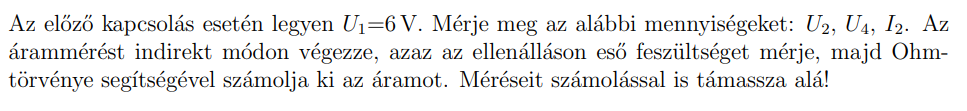

[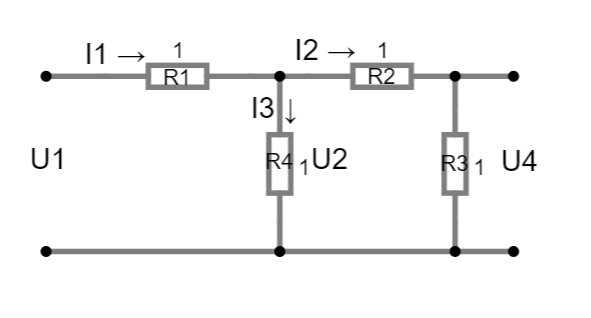](https://www.falstad.com/circuit/circuitjs.html?ctz=CQAgjCAMB0l3BWcMBMcUHYMGZIA4UA2ATmIxAUgpABZsKBTAWjDACgB3EbFcMXwjT69IbAE4hBw8DSGsR4TuEJV5y1SjxRx68Jt1hiC9lzArwR3Wi2jTs6WdX9tp82rAZC00RI9e1KAj+zqpKgcG84Xo2YUHSmlpqPiBR-FqplqFcGZFx1i5W+Cl5RbaFWjwppbFe+QlVMQAeKfRm9HTKXnJeAKrszcTB5KwQ-FRyvABK-Q18tSithrR6IJMobM0oNIlSRK2E5BOr2BvgCLxtysOEXSuTNKcIrZBIeP5F3SAAkmAAOgDOgCTCU5gexgbBIMzEcDYLSfL7YAGAZMIQYREpB6GhRpBbmZvigAcDmh5rq0yJ1lnieutNnhRlJcPTDsoQD0HkA)

### Adatok

### Képletek


$$I=\frac{U}{R}$$


$R_e =R_1 +R_2 +\ldotp \ldotp +R_n$ Soros kapcsolásnál

$R_e =\frac{1}{\frac{1}{R_1 }+\frac{1}{R_2 }+\ldotp \ldotp +\frac{1}{R_n }}$ Párhuzamos kapcsolásnál

$I_1 +I_2 +\ldotp \ldotp +I_n =0$ csomóponti törvény előjeles áram erősségek összegére.

### Adatok

U_1 = 6;
R_1 = 1;
R_2 = 1;
R_3 = 1;
R_4 = 1;

### Számolás

Először is számoljuk ki az áramkör eredő áramkörét. A jobb alsó pont azonos a bal alsó ponttal, így a 2. feladat első kérdésére a válasz azonos ezzel az értékkel.

R_ps = R_2 + R_3;
R_ep = 1 / ((1 / R_4) + (1 / R_ps));
R_e = R_1 + R_ep;

A feszültséggel és az eredő ellenállással megállapíthatjuk az áramkörben haladó áram erősségét.

I_1 = U_1 / R_e

I_1 = 3.6000

Az $I_1$ egyenlő a csomóponti törvény alapján $I_2 \;\mathrm{és}\;I_3$-al, amik megkaphatóak Ohm törvénnyel az ellenállás értékek és a rajtuk eső feszültségből.

$I_2 =\frac{U_2 }{R_2 +R_3 }$, $I_3 =\frac{U_2 }{\mathrm{R4}}$

Az $U_2$ megállapítható a következő képlettel: $U_2 =U_1 -I_{1\;} \cdot R_{1\;}$

U_2 = U_1 - (I_1 * R_1)

U_2 = 2.4000

I_2 = U_2 / (R_2 + R_3)

I_2 = 1.2000

I_3 = U_2 / R_4

I_3 = 2.4000

Miután ismerjük az $I_2$ áramerősséget könnyen megállapíthatjuk az $U_4$feszültséget. 

U_4 = R_3 * I_2

U_4 = 1.2000

### Ellenőrzés

[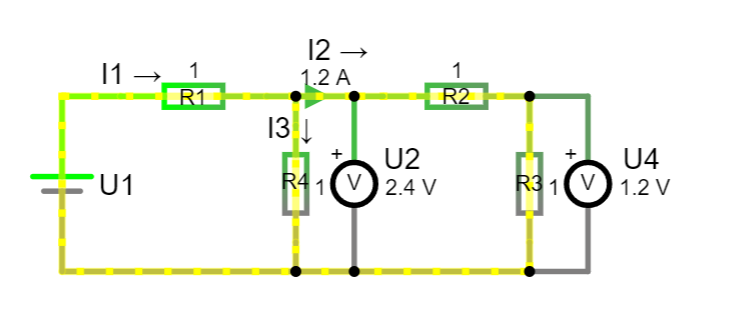](https://www.falstad.com/circuit/circuitjs.html?ctz=CQAgjCAMB0l3BWcMBMcUHYMGZIA4UA2ATmIxAUgpABZsKBTAWjDACgB3EbFcMXwjT69IbAE4hBw8DSGsR4TuEJV5y1SjxRx68Jt1hiC9lzArwR3Wi2jTs6WdX9tE69M1a1qpR-d5P+rYgvmo8TiI6Ifohlt5cMby+bkGGifjB-sHpKeZuPFk2Ppl5aAXaAB4gxIR85KwQ-FRyvABK7JUoNE41KAhIrMS0eiAtKGwdeKpSKMT9hOTNI9jj4Ai8ZvRmdYQ1iy00KwibkEh4NWDpcjUAkmAAOgDOgEmEK2D2YNhzgx9aVyDX2EegGTCV47KrrUhVJB-a4oR4vDrpMBrYL6ZHQ5QgACqY0q2Gw3xRn0JGLM2IOADduGktPkvFBaFQalQWdAEId1mCMJzBn8sewAA7U8LCsr0Fk+JHOVLSHJUNwy5JsIUytSK9Li7TYDBTEWq6UM0RAA)